# **Case Study: Wind Turbine High-Speed Bearing Prognosis**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

This case study a slight modification of a tutorial by Mathworks. 

This example shows how to build an exponential degradation model to predict the Remaining Useful Life (RUL) of a wind turbine bearing in real time. The exponential degradation model predicts the RUL based on its parameter priors and the latest measurements (historical run-to-failure data can help estimate the model parameters priors, but they are not required). 

The model is able to detect the significant degradation trend in real time and updates its parameter priors when a new observation becomes available. The example follows a typical prognosis workflow: data import and exploration, feature extraction and postprocessing, feature importance ranking and fusion, model fitting and prediction, and performance analysis.

Requirement

- Preditive Maintenance Toolbox

## Dataset

The dataset is collected from a 2MW wind turbine high-speed shaft driven by a 20-tooth pinion gear [1]. A vibration signal of 6 seconds was acquired each day for 50 consecutive days (there are 2 measurements on March 17, which are treated as two days in this example). An inner race fault developed and caused the failure of the bearing across the 50-day period. 

## (option) Loading Trained Data and Final Results

Since it takes quite some time to process the training, you may load pre-trained variables and skip all the processing to view the final results

%load('WindTurbinePrognosis-AfterTrain.mat');
bDataNotRead=1

bDataNotRead = 1

## Data Import

The measurement time step for the full dataset is 1 day.

Download the  dataset [https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data](https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data,)

- Download the entire repository as a zip file

- Unzip the file under the directory of `/IAIA/Dataset/WindTurbineHighSpeedBearingPrognosis-Data-master/`

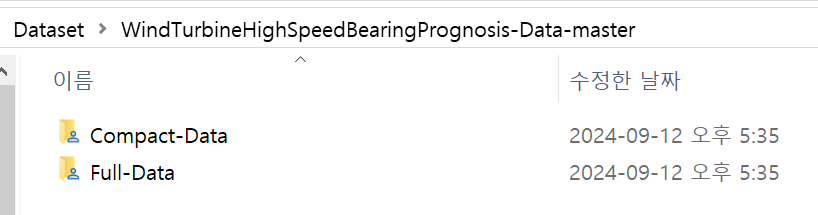

Create a `fileEnsembleDatastore` of the wind turbine data. 

- The data contains a vibration signal and a tachometer signal. 

- The `fileEnsembleDatastore` will parse the file name and extract the date information as `IndependentVariables`. 

% Change the directory path where the dataset is located

if(bDataNotRead)
    bDataNotRead=0;
    hsbearing = fileEnsembleDatastore(...
        fullfile('.', '../../Dataset/WindTurbineHighSpeedBearingPrognosis-Data-master','Full-Data'), ...
        '.mat');
    timeUnit = 'day';
    
    hsbearing.DataVariables = ["vibration", "tach"];
    hsbearing.IndependentVariables = "Date";
    hsbearing.SelectedVariables = ["Date", "vibration", "tach"];
    hsbearing.ReadFcn = @helperReadData;
    hsbearing.WriteToMemberFcn = @helperWriteToHSBearing;
    tall(hsbearing);  % Show Elements of Seleceted Variables
end

Sample rate of vibration signal is 97656 Hz. 

fs = 97656; % Hz

## Data Exploration

This section explores the data in both time domain and frequency domain and seeks inspiration of what features to extract for prognosis purposes.

First visualize the vibration signals in the time domain. In this dataset, there are 50 vibration signals of 6 seconds measured in 50 consecutive days. 

Now plot the 50 vibration signals one after each other.

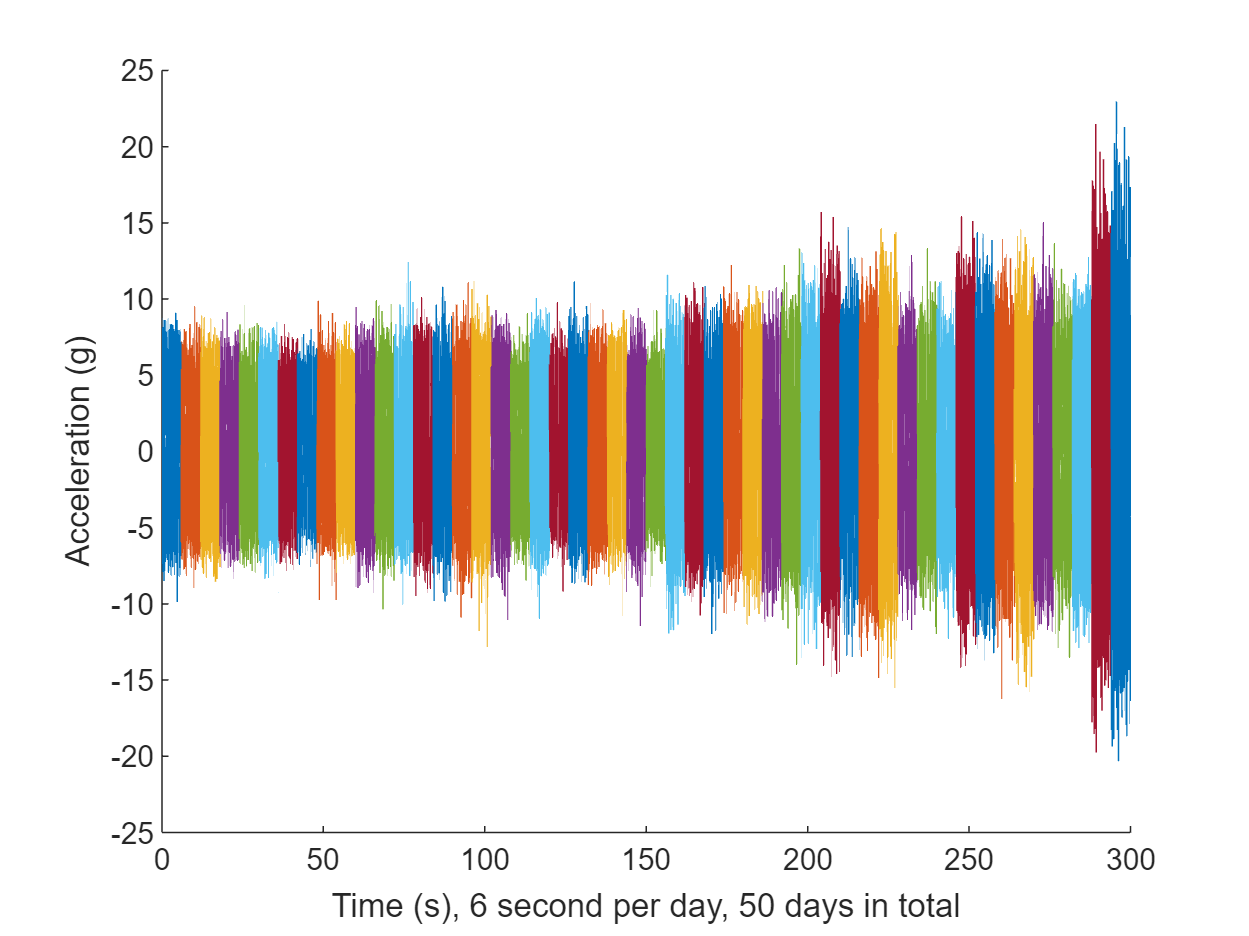

reset(hsbearing)
tstart = 0;
figure
hold on
while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.vibration{1};
    t = tstart + (1:length(v))/fs;
    % Downsample the signal to reduce memory usage
    plot(t(1:10:end), v(1:10:end))
    tstart = t(end);
end
hold off
xlabel('Time (s), 6 second per day, 50 days in total')
ylabel('Acceleration (g)')

The vibration signals in time domain reveals an increasing trend of the signal impulsiveness. Indicators quantifying the impulsiveness of the signal, such as kurtosis, peak-to-peak value, crest factors *etc.*, are potential prognostic features for this wind turbine bearing dataset [2]. 

On the other hand, **spectral kurtosis** is considered powerful tool for wind turbine prognosis in frequency domain [3]. 

To visualize the spectral kurtosis changes along time, plot the spectral kurtosis values as a function of frequency and the measurement day.

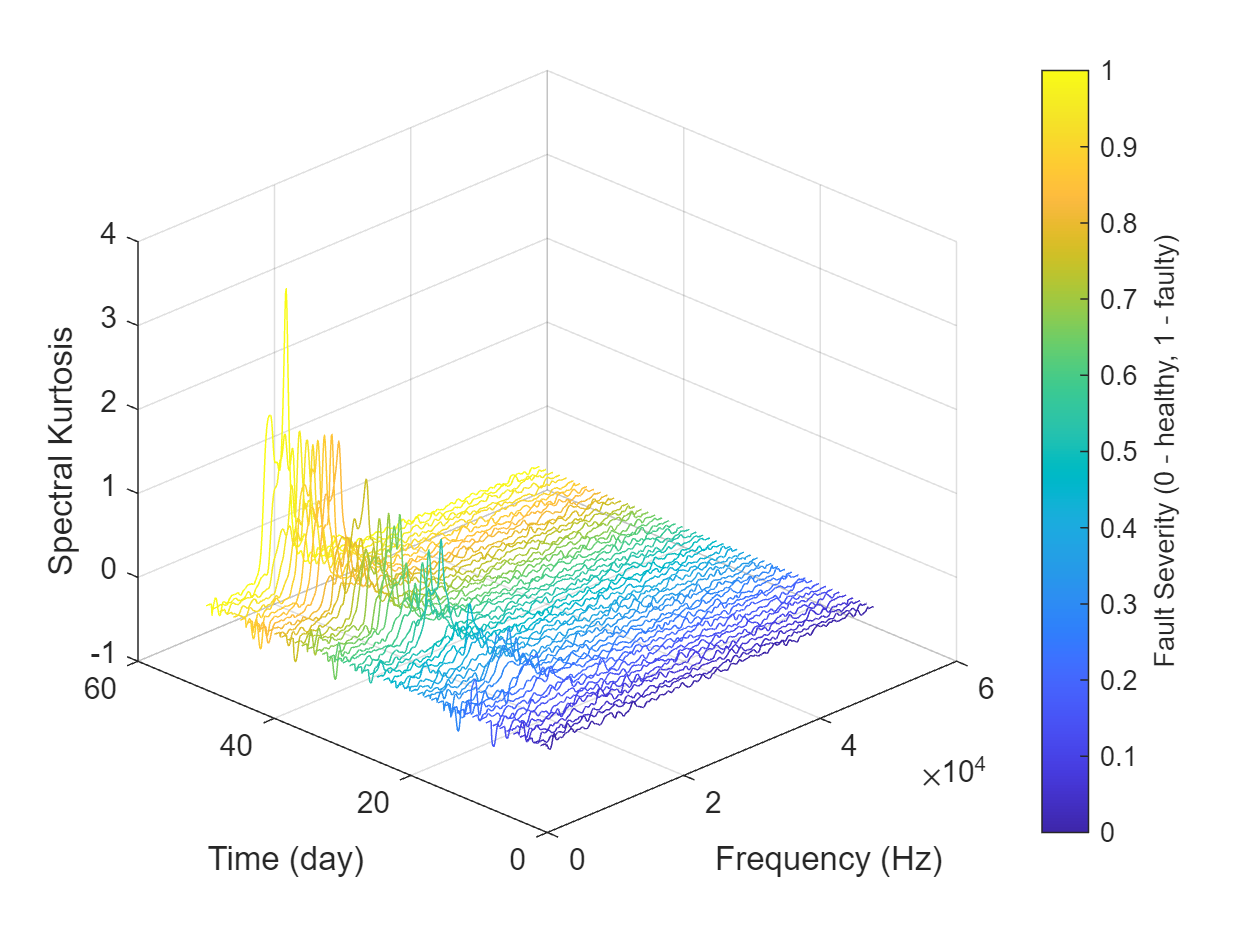

hsbearing.DataVariables = ["vibration", "tach", "SpectralKurtosis"];
colors = parula(50);
figure
hold on
reset(hsbearing)
day = 1;
while hasdata(hsbearing)
    data = read(hsbearing);
    data2add = table;
    
    % Get vibration signal and measurement date
    v = data.vibration{1};
    
    % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);
    data2add.SpectralKurtosis = {table(F, SK)};
    
    % Plot the spectral kurtosis
    plot3(F, day*ones(size(F)), SK, 'Color', colors(day, :))
    
    % Write spectral kurtosis values
    writeToLastMemberRead(hsbearing, data2add);
    
    % Increment the number of days
    day = day + 1;
end
hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on
view(-45, 30)
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')

Fault Severity indicated in colorbar is the measurement date normalized into 0 to 1 scale. 

It is observed that the spectral kurtosis value around 10 kHz gradually increases as the machine condition degrades. Statistical features of the spectral kurtosis, such as mean, standard deviation *etc.*, will be potential indicators of the bearing degradation [3].

## Feature Extraction

Based on the analysis in the previous section, a collection of statistical features derived from time-domain signal and spectral kurtosis are going to be extracted. More mathematical details about the features are provided in [2-3].

 First, pre-assign the feature names in DataVariables before writing them into the fileEnsembleDatastore.

hsbearing.DataVariables = [hsbearing.DataVariables; ...
    "Mean"; "Std"; "Skewness"; "Kurtosis"; "Peak2Peak"; ...
    "RMS"; "CrestFactor"; "ShapeFactor"; "ImpulseFactor"; "MarginFactor"; "Energy"; ...
    "SKMean"; "SKStd"; "SKSkewness"; "SKKurtosis"];

Compute feature values for each ensemble member.

hsbearing.SelectedVariables = ["vibration", "SpectralKurtosis"];
reset(hsbearing)
while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.vibration{1};
    SK = data.SpectralKurtosis{1}.SK;
    features = table;
    
    % Time Domain Features
    features.Mean = mean(v);
    features.Std = std(v);
    features.Skewness = skewness(v);
    features.Kurtosis = kurtosis(v);
    features.Peak2Peak = peak2peak(v);
    features.RMS = rms(v);
    features.CrestFactor = max(v)/features.RMS;
    features.ShapeFactor = features.RMS/mean(abs(v));
    features.ImpulseFactor = max(v)/mean(abs(v));
    features.MarginFactor = max(v)/mean(abs(v))^2;
    features.Energy = sum(v.^2);
    
    % Spectral Kurtosis related features
    features.SKMean = mean(SK);
    features.SKStd = std(SK);
    features.SKSkewness = skewness(SK);
    features.SKKurtosis = kurtosis(SK);
    
    % write the derived features to the corresponding file
    writeToLastMemberRead(hsbearing, features);
end

Select the independent variable `Date` and all the extracted features to construct the feature table.

hsbearing.SelectedVariables = ["Date", "Mean", "Std", "Skewness", "Kurtosis", "Peak2Peak", ...
    "RMS", "CrestFactor", "ShapeFactor", "ImpulseFactor", "MarginFactor", "Energy", ...
    "SKMean", "SKStd", "SKSkewness", "SKKurtosis"];

Since the feature table is small enough to fit in memory (50 by 15), gather the table before processing. 

- For big data, it is recommended to perform operations in tall format until you are confident that the output is small enough to fit in memory.

featureTable = gather(tall(hsbearing));

로컬 MATLAB 세션을(를) 사용하여 tall 표현식을 실행하는 중:
- 1/1 통과: 38초 소요됨
실행 시간: 38초


Convert the table to timetable so that the time information is always associated with the feature values.

featureTable = table2timetable(featureTable)

featureTable = 50×15 timetable
           Date             Mean       Std       Skewness      Kurtosis    Peak2Peak     RMS      CrestFactor    ShapeFactor    ImpulseFactor    MarginFactor      Energy        SKMean       SKStd      SKSkewness    SKKurtosis
    ___________________    _______    ______    ___________    ________    _________    ______    ___________    ___________    _____________    ____________    __________    __________    ________    __________    __________

    2013-03-07 01:57:46    0.34605    2.2705      0.0038699     2.9956      21.621      2.2967      4.9147         1.2535          6.1607           3.3625       3.0907e+06     0.0013007     0.02575     -0.22011       3.3392  
    2013-03-08 02:34:21    0.24409    2.0621      0.0030103     3.0195       19.31      2.0765      4.9129         1.2545           6.163           3.7231       2.5266e+06     0.0046258    0.020869     0.057756       3.3494  
    2013-03-09 02:33:43    0.21873    2.1036     -0.0010289     

## Feature Postprocessing

Extracted features are usually associated with noise. The noise with opposite trend can sometimes be harmful to the RUL prediction. 

In addition, one of the feature performance metrics, **monotonicity is NOT robust to noise**. 

Therefore, a causal moving mean filter with a lag window of 5 steps is applied to the extracted features, where "causal" means no future value is used in the moving mean filtering.

variableNames = featureTable.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), featureTable);
featureTableSmooth.Properties.VariableNames = variableNames;

Here is an example showing the feature before and after smoothing (moving window).

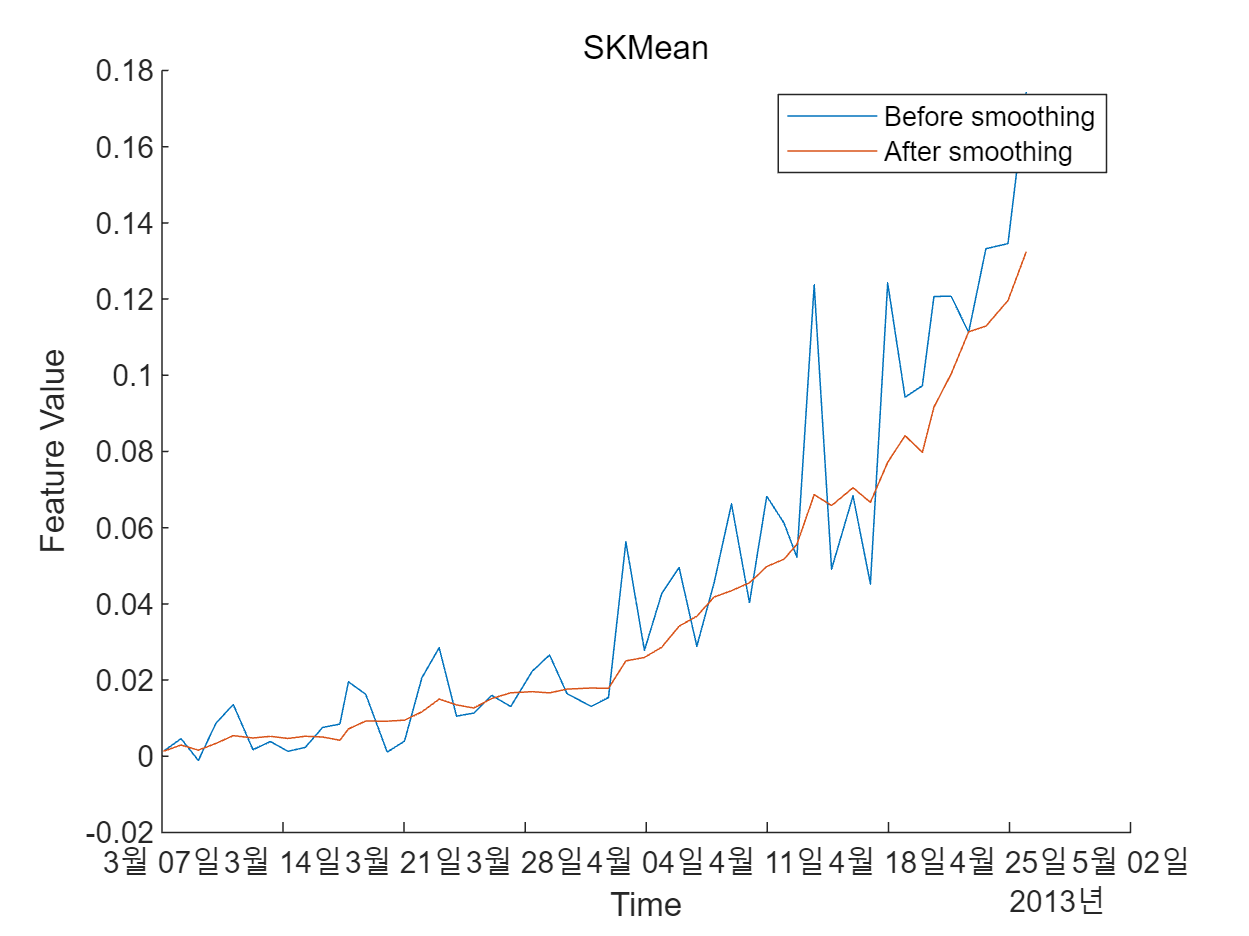

figure
hold on
plot(featureTable.Date, featureTable.SKMean)
plot(featureTableSmooth.Date, featureTableSmooth.SKMean)
hold off
xlabel('Time')
ylabel('Feature Value')
legend('Before smoothing', 'After smoothing')
title('SKMean')

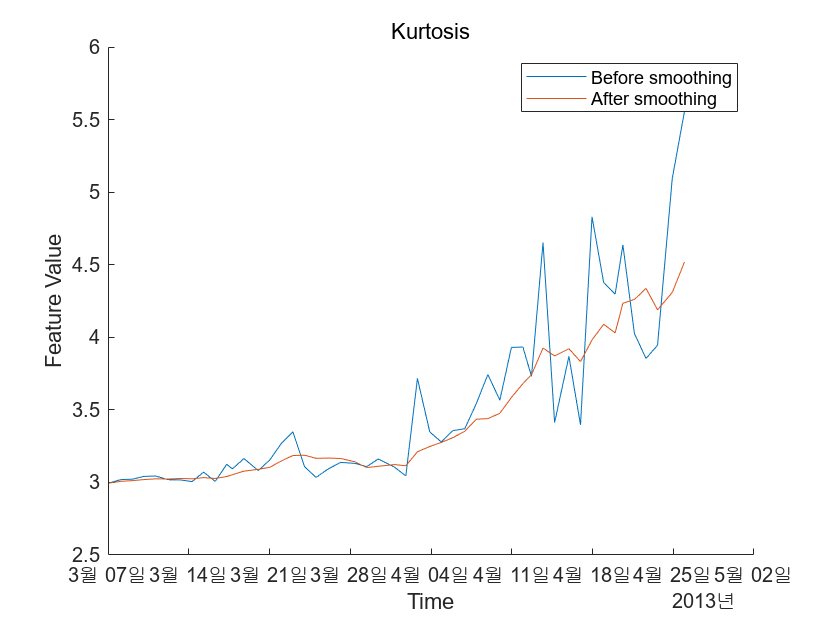

figure
hold on
plot(featureTable.Date, featureTable.Kurtosis)
plot(featureTableSmooth.Date, featureTableSmooth.Kurtosis)
hold off
xlabel('Time')
ylabel('Feature Value')
legend('Before smoothing', 'After smoothing')
title('Kurtosis')

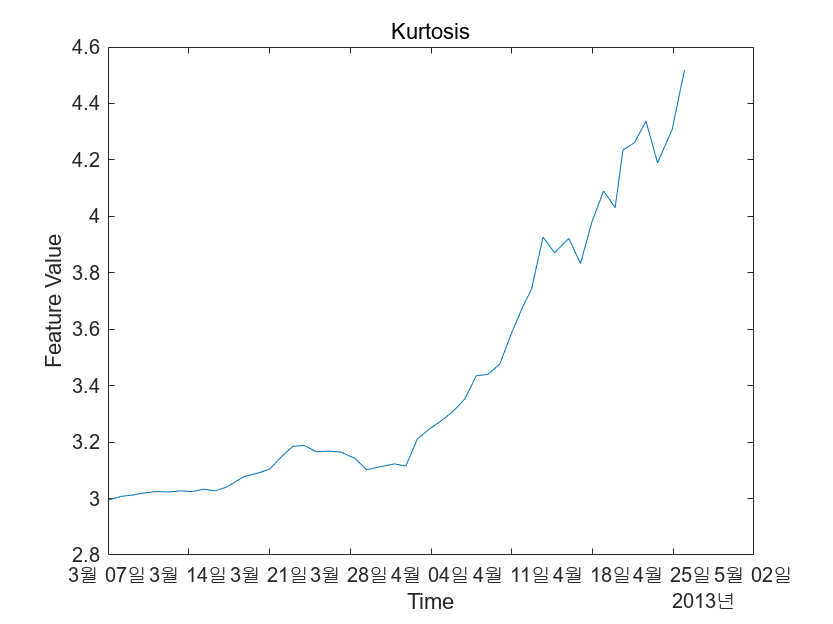



% Plot some features over time after applying smoothing
figure
plot(featureTableSmooth.Date, featureTableSmooth.Kurtosis)
hold off
xlabel('Time')
ylabel('Feature Value')
title('Kurtosis')

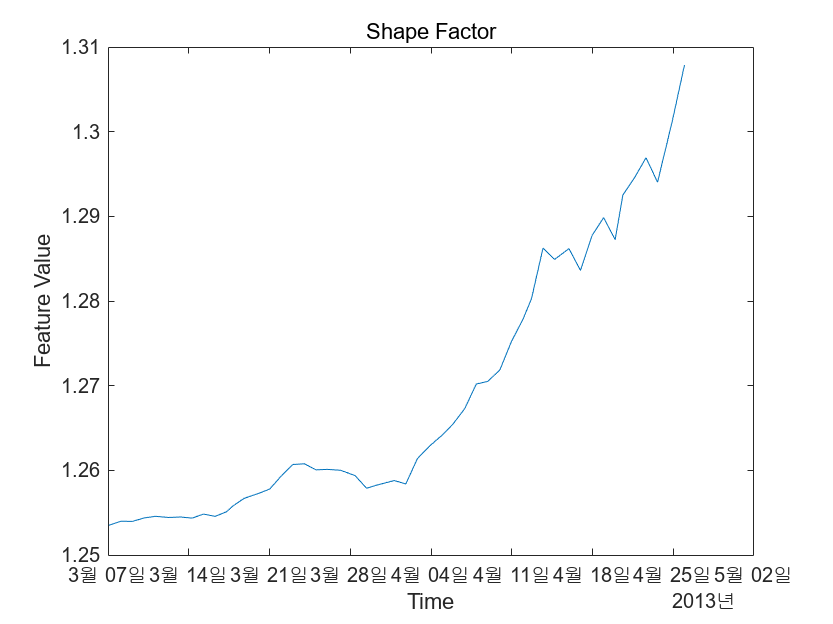


figure
plot(featureTableSmooth.Date, featureTableSmooth.ShapeFactor)
hold off
xlabel('Time')
ylabel('Feature Value')
title('Shape Factor')

Moving mean smoothing introduces a time delay of the signal, but the delay effect can be mitigated by selecting proper threshold in the RUL prediction.

## Training Data

In practice, the data of the whole life cycle is not available when developing the prognostic algorithm, but it is reasonable to assume that some data in the early stage of the life cycle has been collected. Hence data collected in the first 20 days (40% of the life cycle) is treated as training data. The following feature importance ranking and fusion is only based on the training data.

breaktime = datetime(2013, 3, 27);
breakpoint = find(featureTableSmooth.Date < breaktime, 1, 'last');
trainData = featureTableSmooth(1:breakpoint, :);

## Feature Importance Ranking

**Monotonicity** proposed by [3] is used to quantify the merit of the features for prognosis purpose.

Monotonicity of $i$th feature $x_i$ is computed as


$$\textrm{Monotonicity}\left(x_i \right)=\frac{1}{m}\sum_{j=1}^m \frac{\left|\textrm{number}\;\textrm{of}\;\textrm{positive}\;\textrm{diff}\left(x_i^j \right)\;-\;\textrm{number}\;\textrm{of}\;\textrm{negative}\;\textrm{diff}\left(x_i^j \right)\right|}{n-1}$$


where $n$ is the number of measurement points, in this case $n=50$. $m$ is the number of machines monitored, in this case $m=1$. $x_i^j$ is the $i$th feature measured on $j$th machine. $\textrm{diff}\left(x_i^j \right)=x_i^j \left(t\right)-x_i^j \left(t-1\right)$, i.e. the difference of the signal $x_i^j$.

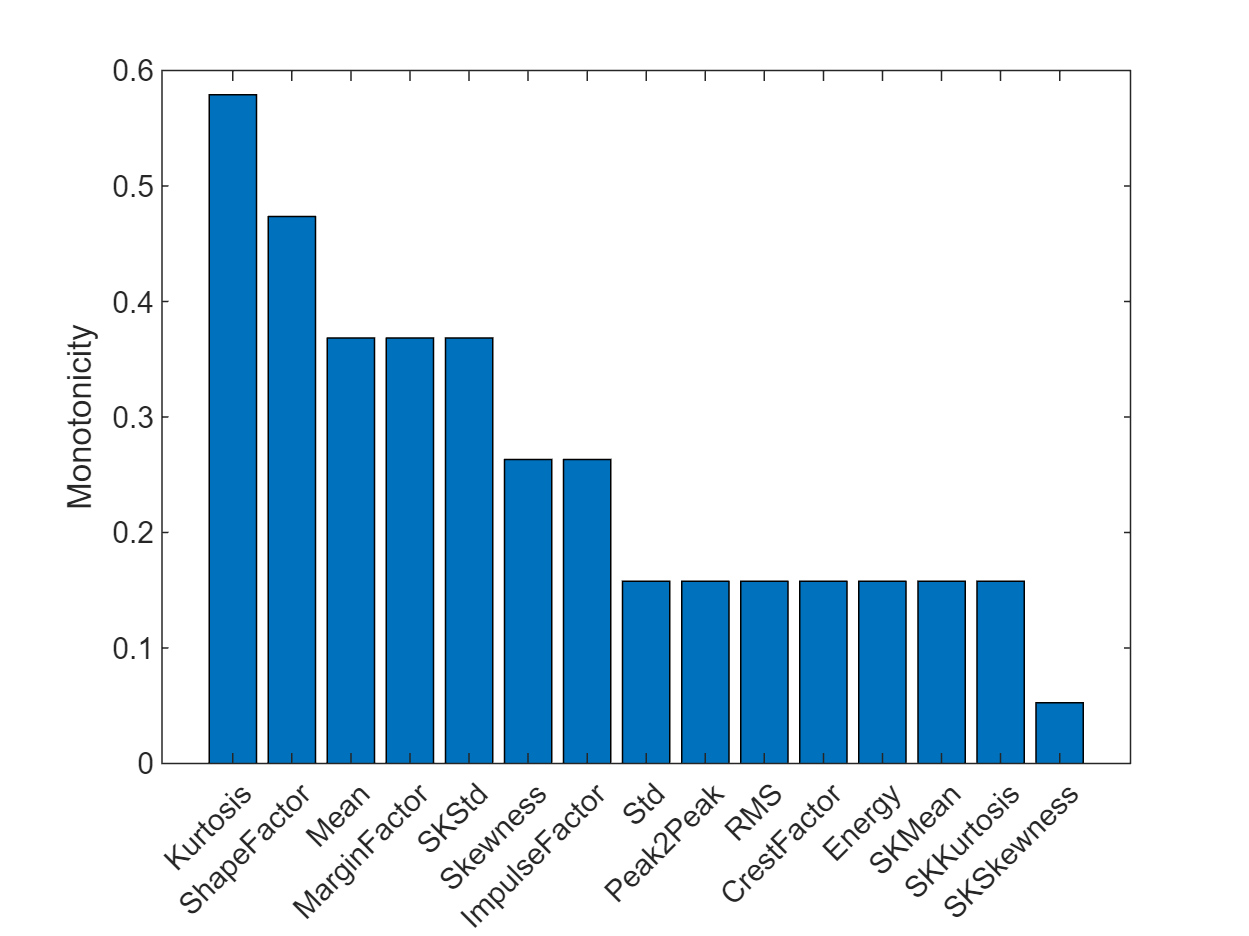

% Since moving window smoothing is already done, set 'WindowSize' to 0 to
% turn off the smoothing within the function
featureImportance = monotonicity(trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');

Kurtosis of the signal is the top feature based on the monotonicity. 

Features with feature importance score larger than 0.3 are selected for feature fusion in the next section.

trainDataSelected = trainData(:, featureImportance{:,:}>0.3);
featureSelected = featureTableSmooth(:, featureImportance{:,:}>0.3)

featureSelected = 50×5 timetable
           Date             Mean      Kurtosis    ShapeFactor    MarginFactor     SKStd  
    ___________________    _______    ________    ___________    ____________    ________

    2013-03-07 01:57:46    0.34605     2.9956       1.2535          3.3625        0.02575
    2013-03-08 02:34:21    0.29507     3.0075        1.254          3.5428       0.023309
    2013-03-09 02:33:43    0.26962     3.0125        1.254          3.6541        0.02311
    2013-03-10 03:01:02    0.25565     3.0197       1.2544          3.7722       0.025954
    2013-03-11 03:00:24    0.24756     3.0247       1.2546          3.7793       0.027192
    2013-03-12 06:17:10    0.25519     3.0236       1.2544          3.7479       0.027381
    2013-03-13 06:34:04      0.233     3.0272       1.2545          3.8282       0.027971
    2013-03-14 06:50:41    0.23299     3.0249       1.2544          3.9047       0.028241
    2013-03-15 06:50:03     0.2315      3.033       1.2548        

## Dimension Reduction and Feature Fusion

**Principal Component Analysis (PCA)** is used for dimension reduction and feature fusion in this example. 

Before performing PCA, it is a good practice to normalize the features into the same scale. 

### Normalize Train Data

Note that PCA coefficients and the mean and standard deviation used in normalization are obtained from training data, and applied to the entire dataset.

meanTrain = mean(trainDataSelected{:,:});
sdTrain = std(trainDataSelected{:,:});
trainDataNormalized = (trainDataSelected{:,:} - meanTrain)./sdTrain;
coef = pca(trainDataNormalized);

The mean, standard deviation and PCA coefficients are used to process the entire data set.

PCA1 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

Visualize the data in the space of the first two principal components.

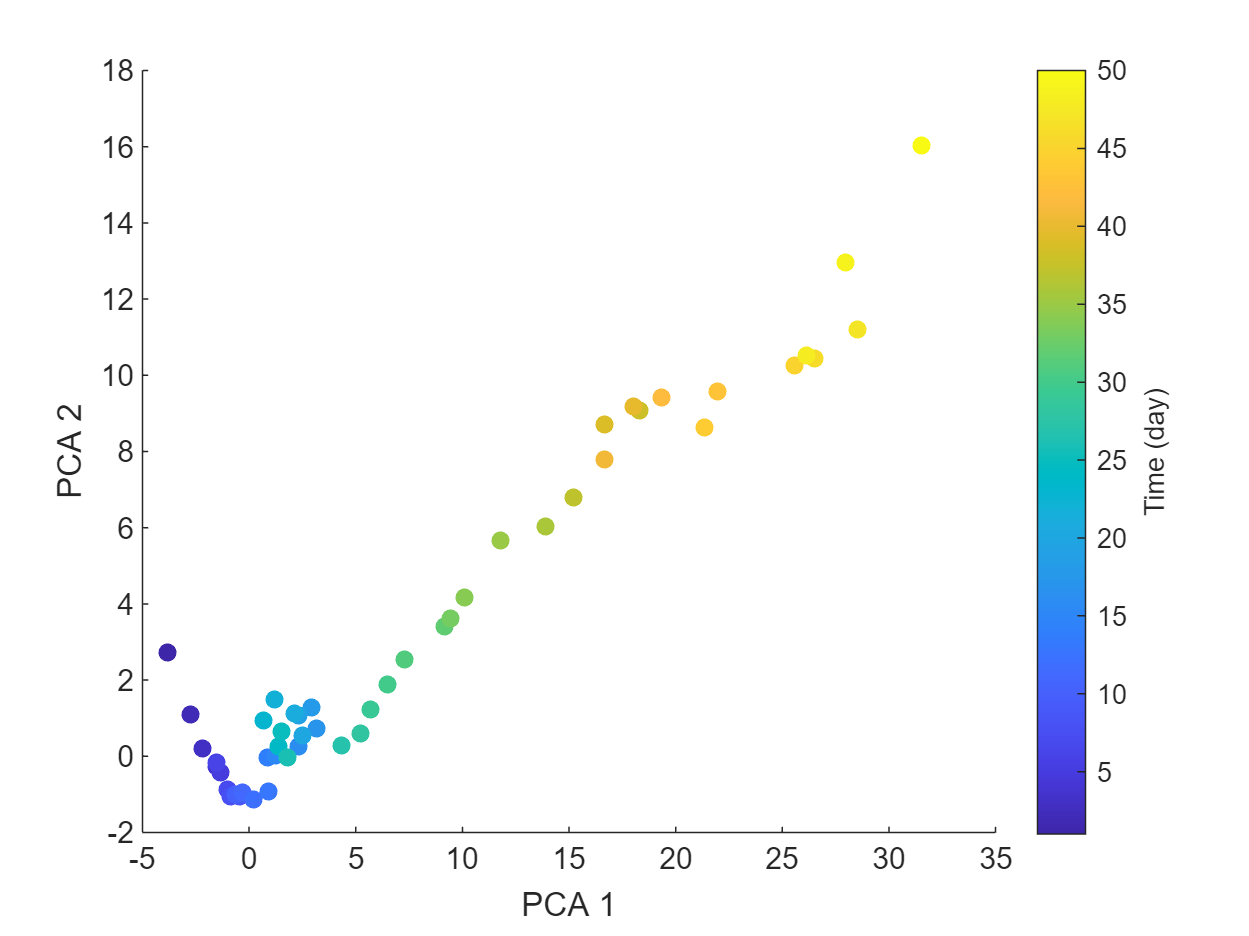

figure
numData = size(featureTable, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])

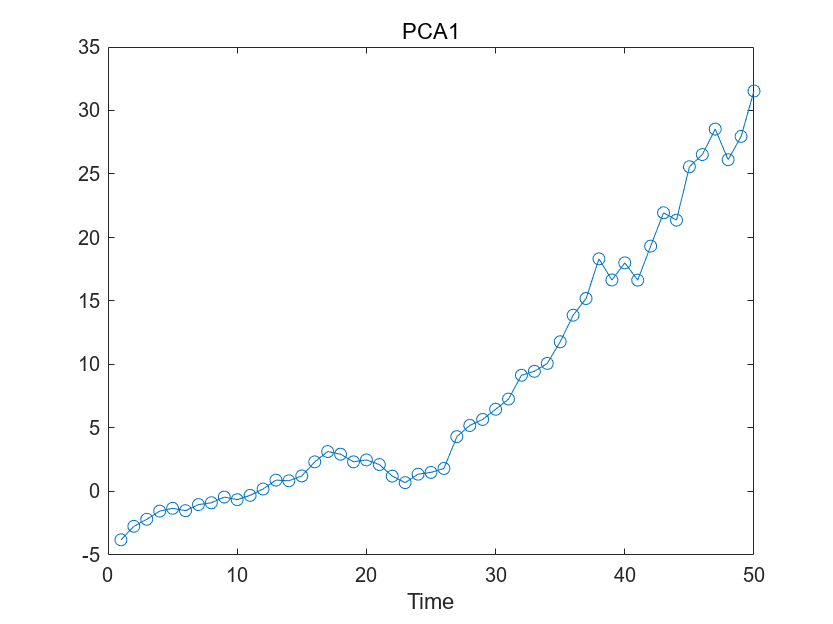


figure
plot(PCA1, '-o')
xlabel('Time')
title('PCA1')

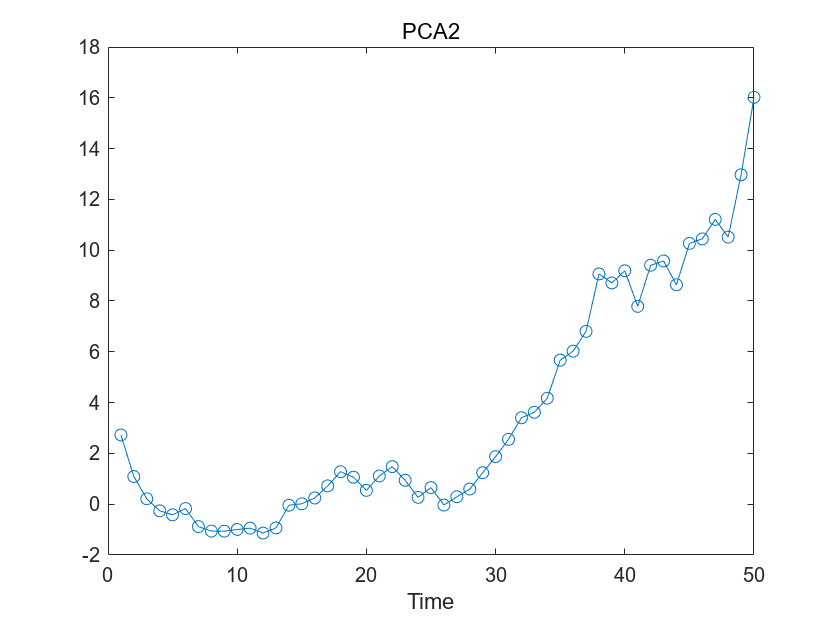

figure
plot(PCA2, '-o')
xlabel('Time')
title('PCA2')

The plot indicates that the first principal component is increasing as the machine approaches to failure. Therefore, the first principal component is a promising fused health indicator.

healthIndicator = PCA1;

Visualize the health indicator.

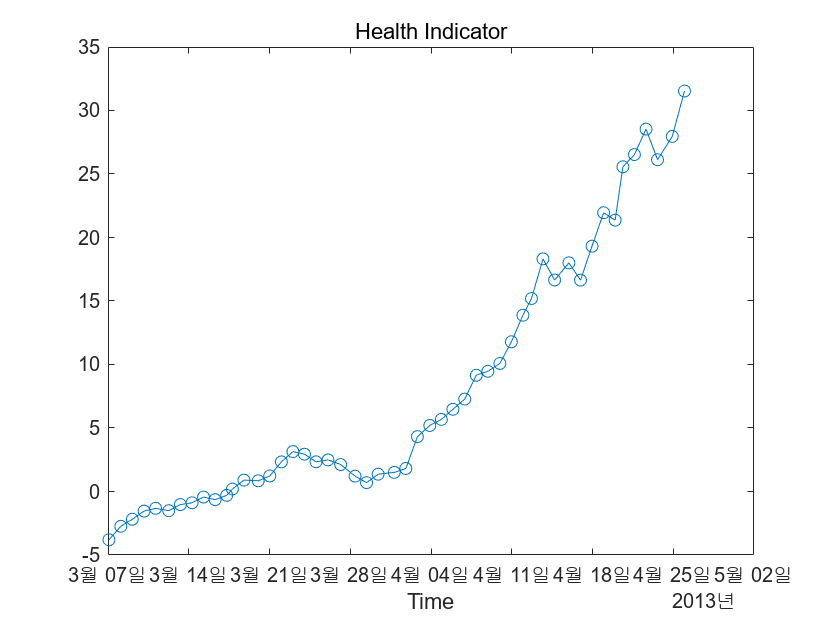

figure
plot(featureSelected.Date, healthIndicator, '-o')
xlabel('Time')
title('Health Indicator')

## Fit Exponential Degradation Models for Remaining Useful Life (RUL) Estimation

Exponential degradation model is defined as


$$h\left(t\right)=\phi +\theta \;\exp \left(\beta \;t+\epsilon \;-\frac{\sigma^2 }{2}\right)$$


where $h\left(t\right)$ is the health indicator as a function of time. $\phi \;$is the intercept term considered as a constant. $\theta$ and $\beta \;$ are random parameters determining the slope of the model, where $\theta \;$is lognormal-distributed and $\beta \;$is Gaussian-distributed. At each time step $t$, the distribution of $\theta \;$and $\beta \;$is updated to the posterior based on the latest observation of $h\left(t\right)$. $\epsilon \;$ is a Gaussian white noise yielding to $N\left(0,\sigma^2 \right)$. The $-\frac{\sigma^2 }{2}$ term in the exponential is to make the expectation of $h\left(t\right)$ satisfy

$E\left\lbrack h\left(t\right)\left|\theta \;,\beta \;\right.\right\rbrack \;=\;\phi +\theta \;\exp \left(\beta \;t\right)$.

Here an Exponential Degradation Model is fit to the health indicator extracted in the last section, and the performances is evaluated in the next section.

First shift the health indicator so that it starts from 0.

healthIndicator = healthIndicator - healthIndicator(1);

The selection of threshold is usually based on the historical records of the machine or some domain-specific knowledge. Since no historical data is available in this dataset, the last value of the health indicator is chosen as the threshold. It is recommended to choose the threshold based on the smoothed (historical) data so that the delay effect of smoothing will be partially mitigated.

threshold = healthIndicator(end);

If historical data is available, use `fit` method provided by `exponentialDegradationModel` to estimate the priors and intercept. However, historical data is not available for this wind turbine bearing dataset.

 The prior of the slope parameters are chosen arbitrarily with large variances ($E\left(\theta \right)=1,\;\textrm{Var}\left(\theta \right)\;={10}^6 ,E\left(\beta \right)=1,\textrm{Var}\left(\beta \right)={10}^6$) so that the model is mostly relying on the observed data. Based on $E\left\lbrack h\left(0\right)\right\rbrack =\phi +E\left(\theta \right)$, intercept $\phi \;$is set to $-1$ so that the model will start from 0 as well. 

The relationship between the variation of health indicator and the variation of noise can be derived as


$$\Delta h\left(t\right)\approx \left(h\left(t\right)-\phi \;\right)\Delta \epsilon \left(t\right)$$


Here the standard deviation of the noise is assumed to cause 10% of variation of the health indicator when it is near the threshold. Therefore, the standard deviation of the noise can be represented as $\frac{10%\cdot \textrm{threshold}}{\textrm{threshold}-\phi \;}$.

The exponential degradation model also provides a functionality to evaluate the significance of the slope. Once a significant slope of the health indicator is detected, the model will forget the previous observations and restart the estimation based on the original priors. The sensitivity of the detection algorithm can be tuned by specifying `SlopeDetectionLevel`. If p value is less than `SlopeDetectionLevel`, the slope is declared to be detected. Here `SlopeDetectionLevel` is set to 0.05.

Now create an exponential degradation model with the parameters discussed above.

mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

Use `predictRUL` and `update` methods to predict the RUL and update the parameter distribution in real time.

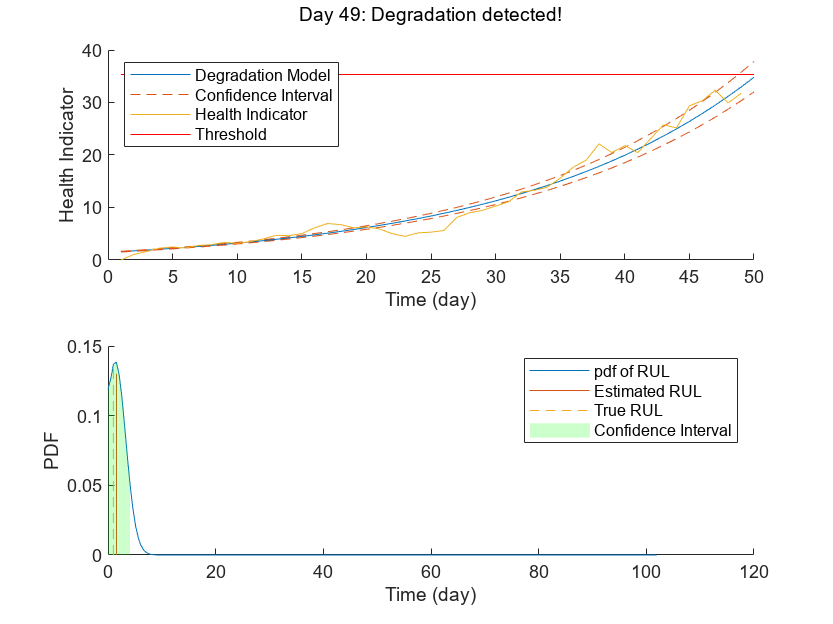

% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs = zeros(totalDay, 2);
pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

Here is the animation of the real-time RUL estimation.

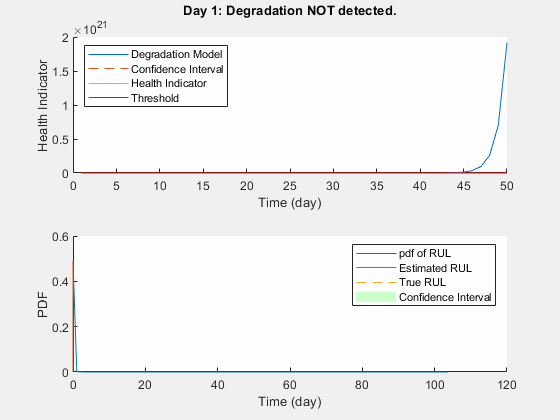

## Performance Analysis

$\alpha$-$\lambda$ plot is used for prognostic performance analysis [5], where $\alpha \;$bound is set to 20%. The probability that the estimated RUL is between the $\alpha$ bound of the true RUL is calculated as a performance metric of the model:


$$\Pr \left(r^* \left(t\right)-\alpha r^* \left(t\right)<r\left(t\right)<r^* \left(t\right)+\alpha r^* \left(t\right)\left|\Theta \left(t\right)\right.\right)$$


where $r\left(t\right)$ is the estimated RUL at time $t$, $r^* \left(t\right)$ is the true RUL at time $t$, $\Theta \left(t\right)$ is the estimated model parameters at time $t$.

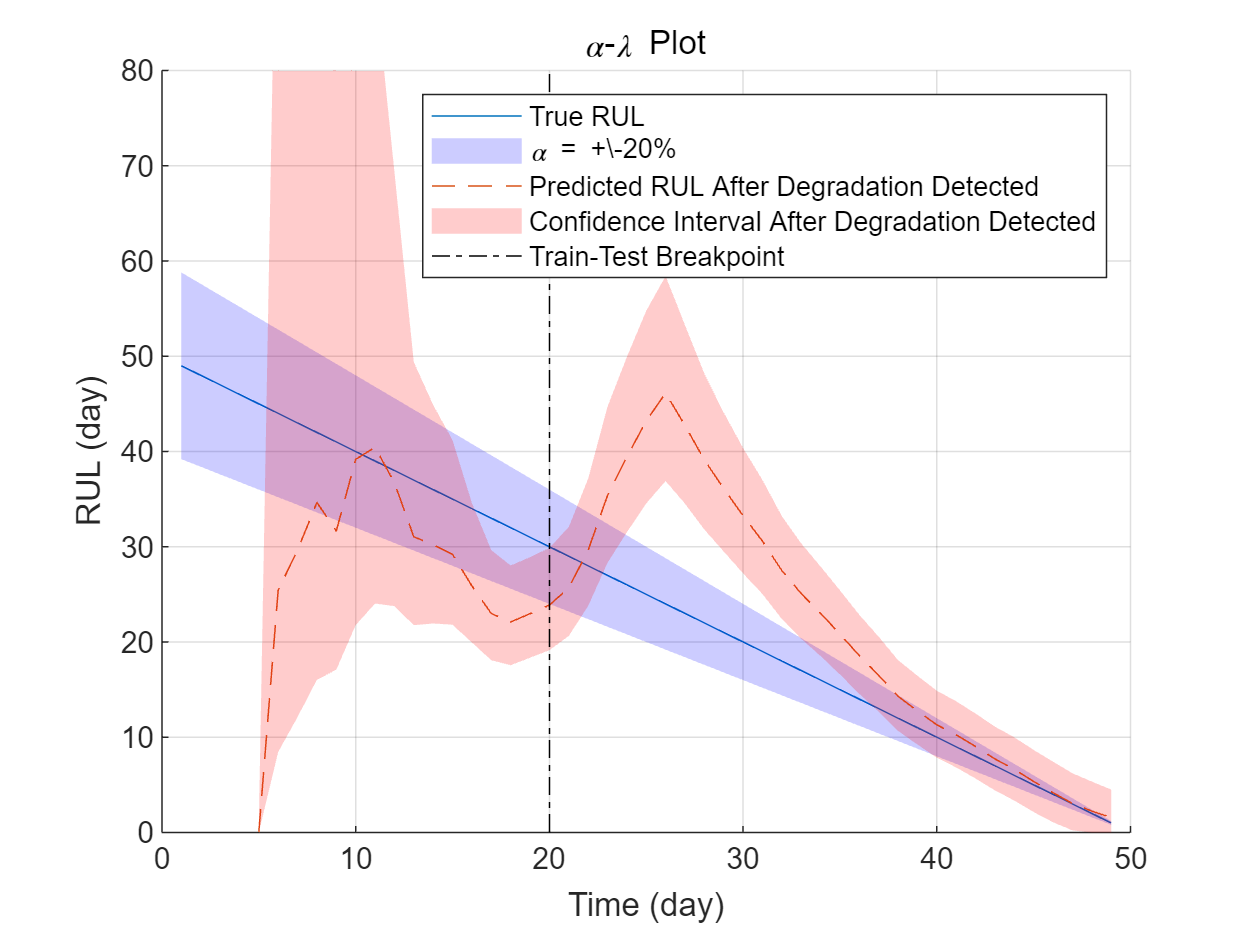

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

Since the preset prior does not reflect the true prior, the model usually need a few time steps to adjust to a proper parameter distribution. The prediction becomes more accurate as more data points are available.

Visualize the probability of the predicted RUL within the $\alpha \;$bound.

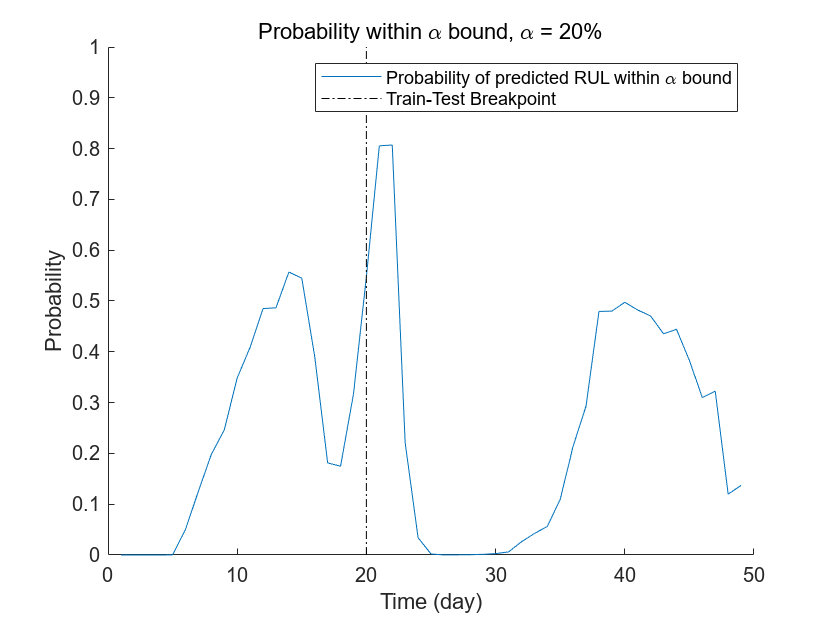

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

## References

[1] Bechhoefer, Eric, Brandon Van Hecke, and David He. "Processing for improved spectral analysis." *Annual Conference of the Prognostics and Health Management Society, New Orleans, LA, Oct*. 2013.

[2] Ali, Jaouher Ben, et al. "Online automatic diagnosis of wind turbine bearings progressive degradations under real experimental conditions based on unsupervised machine learning." *Applied Acoustics* 132 (2018): 167-181.

[3] Saidi, Lotfi, et al. "Wind turbine high-speed shaft bearings health prognosis through a spectral Kurtosis-derived indices and SVR." *Applied Acoustics* 120 (2017): 1-8.

[4] Coble, Jamie Baalis. "Merging data sources to predict remaining useful life–an automated method to identify prognostic parameters." (2010).

[5] Saxena, Abhinav, et al. "Metrics for offline evaluation of prognostic performance." *International Journal of Prognostics and Health Management* 1.1 (2010): 4-23.

*Copyright 2017-2018 The MathWorks, Inc.*